## **Multi-hazard Analysis Scenario Analysis (MhAST) Toolbox**

**Author: Mohammad Bizhanimanzar**

**Source: **

## Section 1: MhAST modules (Flowchart)

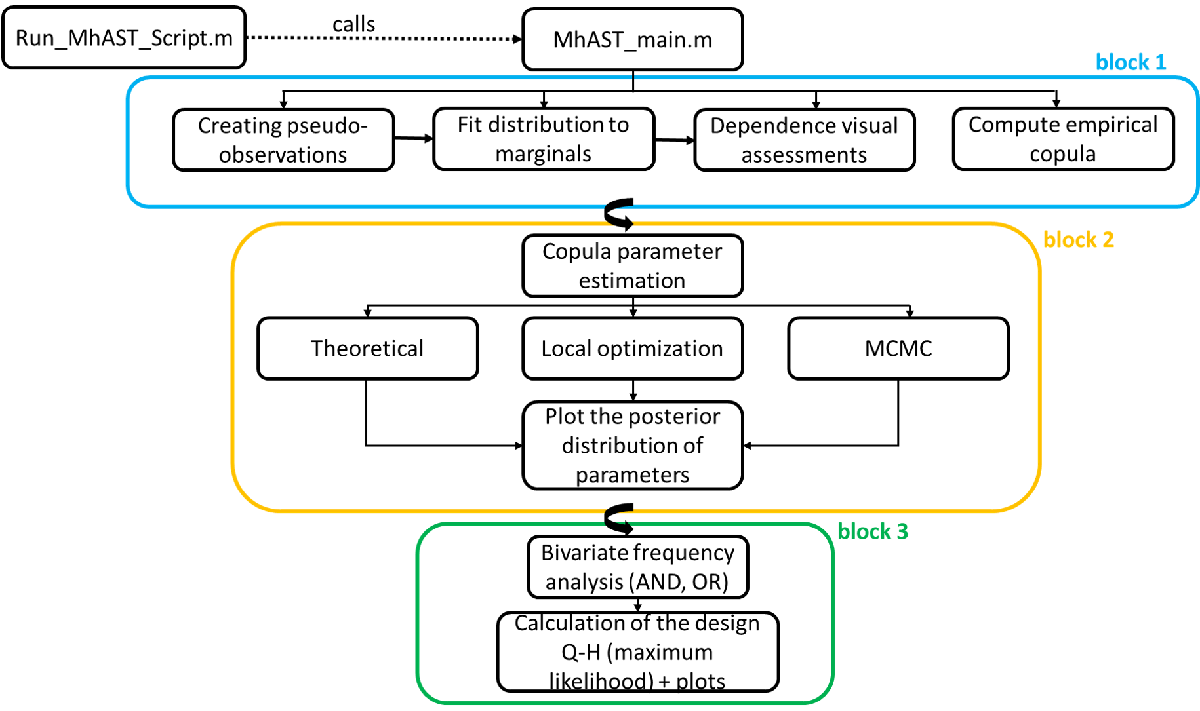

## **Working example**

**Analysis of compound flooding of Saint_Maurice river outlet. Lets take a look at the Run_MhAST_Script.m**

%% User Input
% Data file name
datafile = 'WLcondQ.csv';
handles.title = 'WLcondQ';
% handles.title = 'QcondWL';

% Sampling frequency (how many samples per year?)
handles.SF = 1;
% Design Return Period
handles.DesignRP = 100;
% Number of weighted samples on the design return period curve
handles.WeightedSampleSize = 2000;
% Uncertainty requested?
handles.DesignUnc = 0;
% Name of the variables
handles.U1_name = 'Discharge (m^3/s)';
handles.U2_name = 'Water level (m)';

% Local optimization or Global
handles.Optimization = 'MCMC'; % Local: local optimization; MCMC: both local & global optimization

% Which Copulas to run? Select any combination
% 1: Gaussian, 2: t, 3: Clayton, 4: Frank, 5: Gumbel, 6: Independence, 7: Ali-Mikhail-Haq (AMH), 8: Joe
% 9: Farlie-Gumbel-Morgenstern (FGM), 10: Gumbel-Barnet, 11: Plackett, 12: Cuadras-Auge, 13: Raftery
% 14: Shih-Louis, 15: Linear-Spearman, 16: Cubic, 17: Burr, 18: Nelson, 19: Galambos, 20: Marshal-Olkin
% 21: Fischer-Hinzmann, 22: Roch-Alegre, 23: Fischer-Kock, 24: BB1, 25: BB5, 26: Tawn
handles.ID_CHOSEN = [1:25];

% Calculate pvalues or not? 0: no pvalue; 1: pvalue for the best copula
% selected according to BIC; 2: pvalue for all chosen copulas
handles.pvalue = 2;

handles.Kendall=0;
handles.empiricalcopula = 0; % 1 = add the empirical copula plot to the return periods or 0 (not)

% Load data
if ismac
    addpath([pwd,'/Data'])
elseif ispc
    addpath([pwd,'\Data'])
elseif isunix
    addpath([pwd,'/Data'])
end

try
    handles.data = csvread(datafile,1,4);
catch
    handles.data = load(datafile);
end

#### Now call the MhAST_main.m script. Before running the main function, put a breakpoint at line 571 to investigate the quality of marginal fits and perform the visual assessment of the dependence using K-plot, Chi-plot, and scatterplot of the pseudo-observations. As it was explained in LOT3 report, this step is very important for identifying potential copulas that may represent the observed dependence in the joint dataset.

% Run main MhAST function
[ID_ML,ID_AIC,ID_BIC,Family] = MhAST_main(handles);

'MhAST_main' is not found in the current folder or on the MATLAB path, but exists in:
    U:\Dossier_travail\705300_rehaussement_marin\3- Data\Rehaussement_marine\MhAST_Ver02.05
    U:\Dossier_travail\705300_rehaussement_marin\Rehaussement_marine\MhAST_Ver02.05

Change the MATLAB current folder or add its folder to the MATLAB path.